clear all;
load hw4.mat;

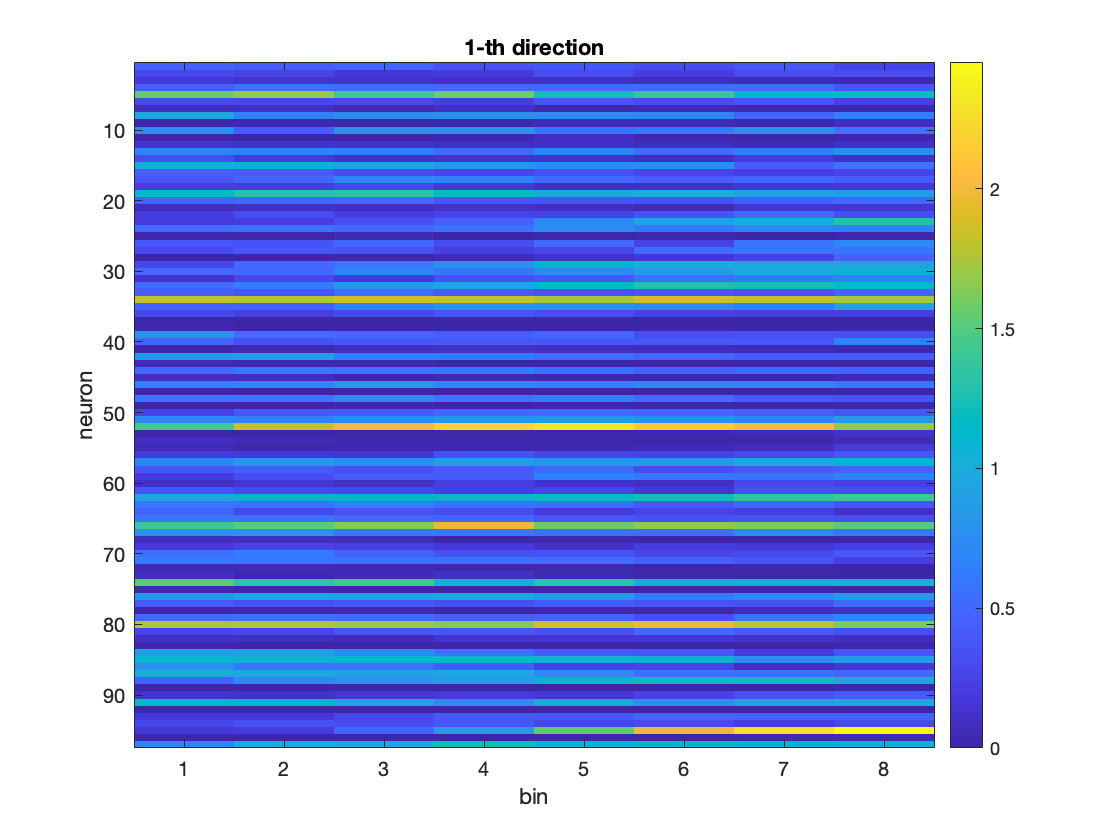

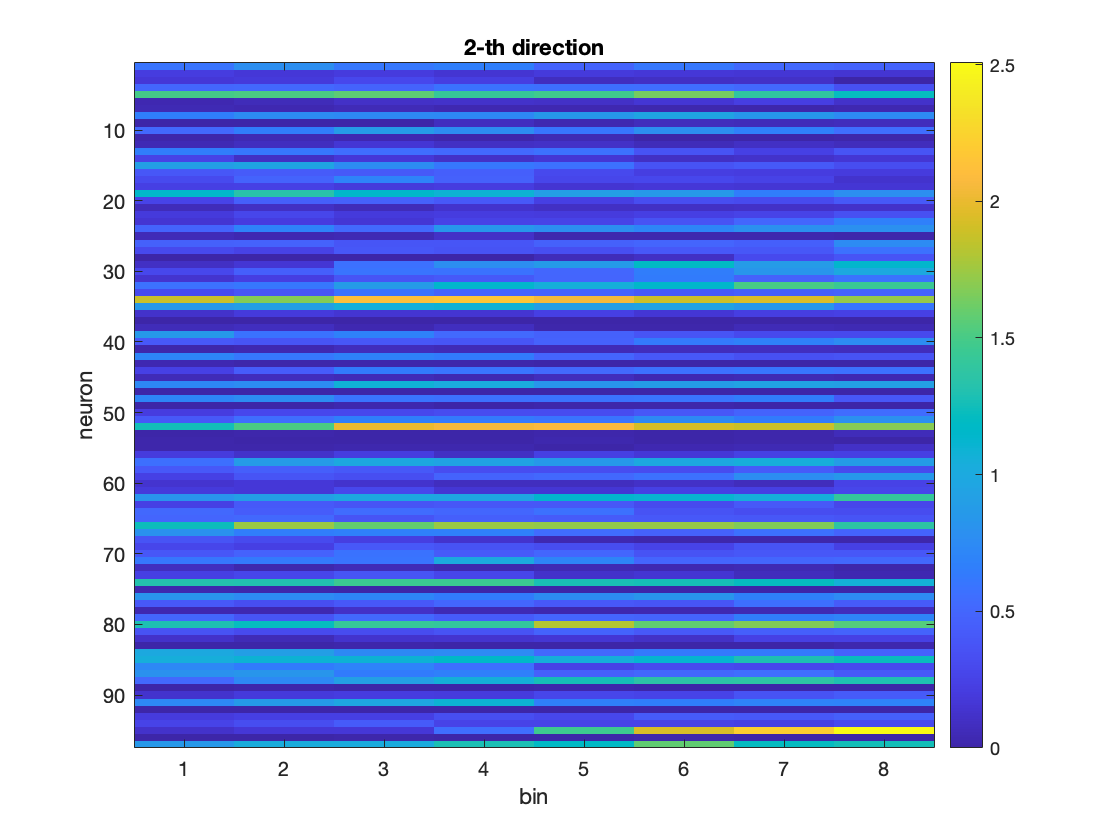

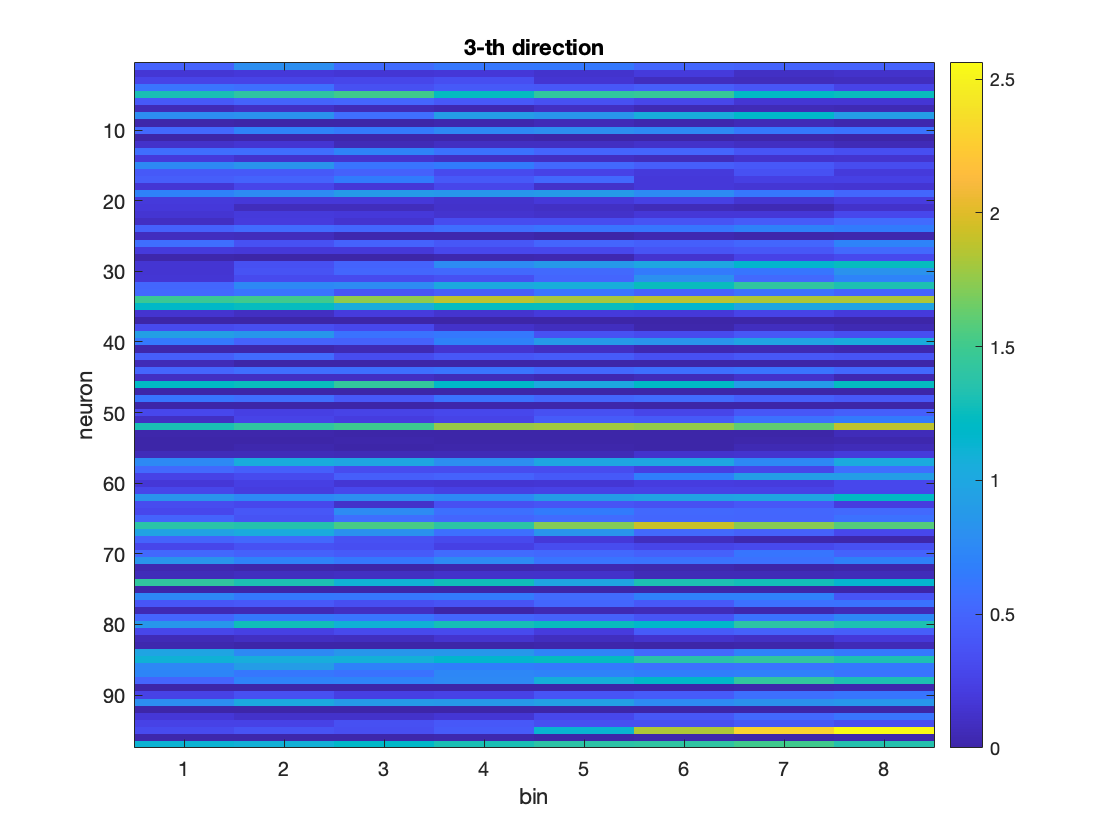

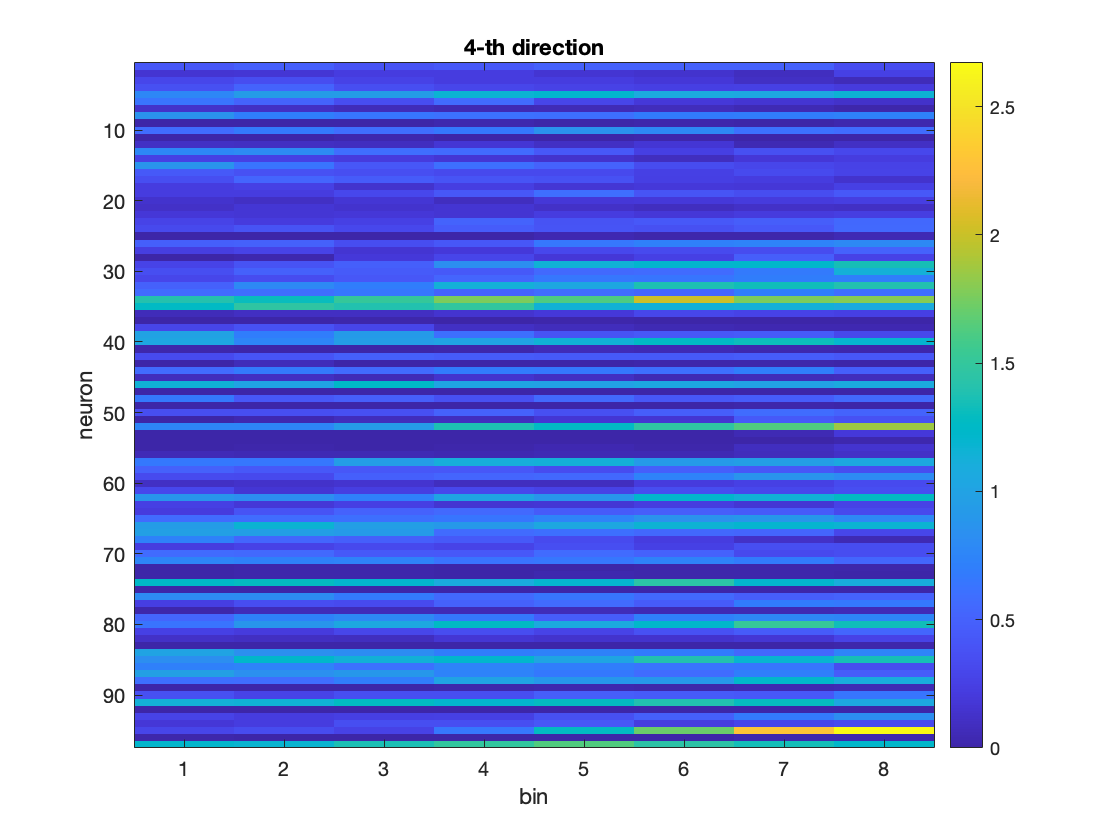

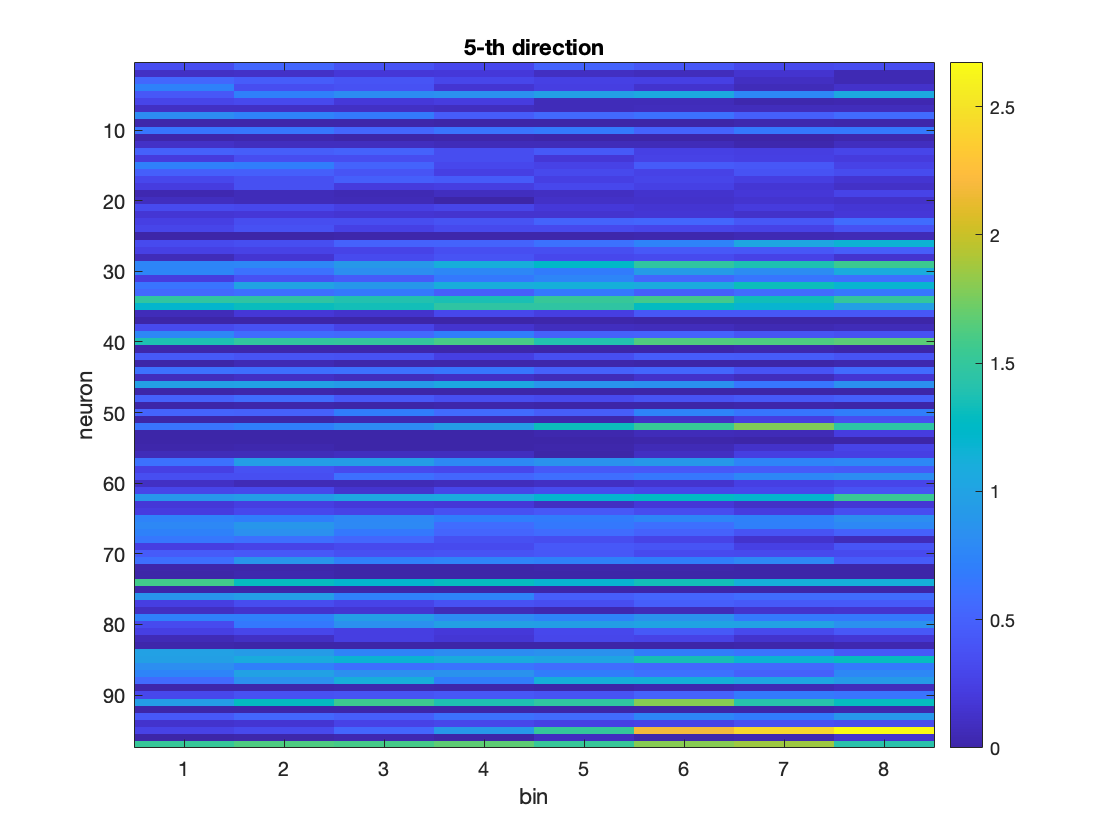

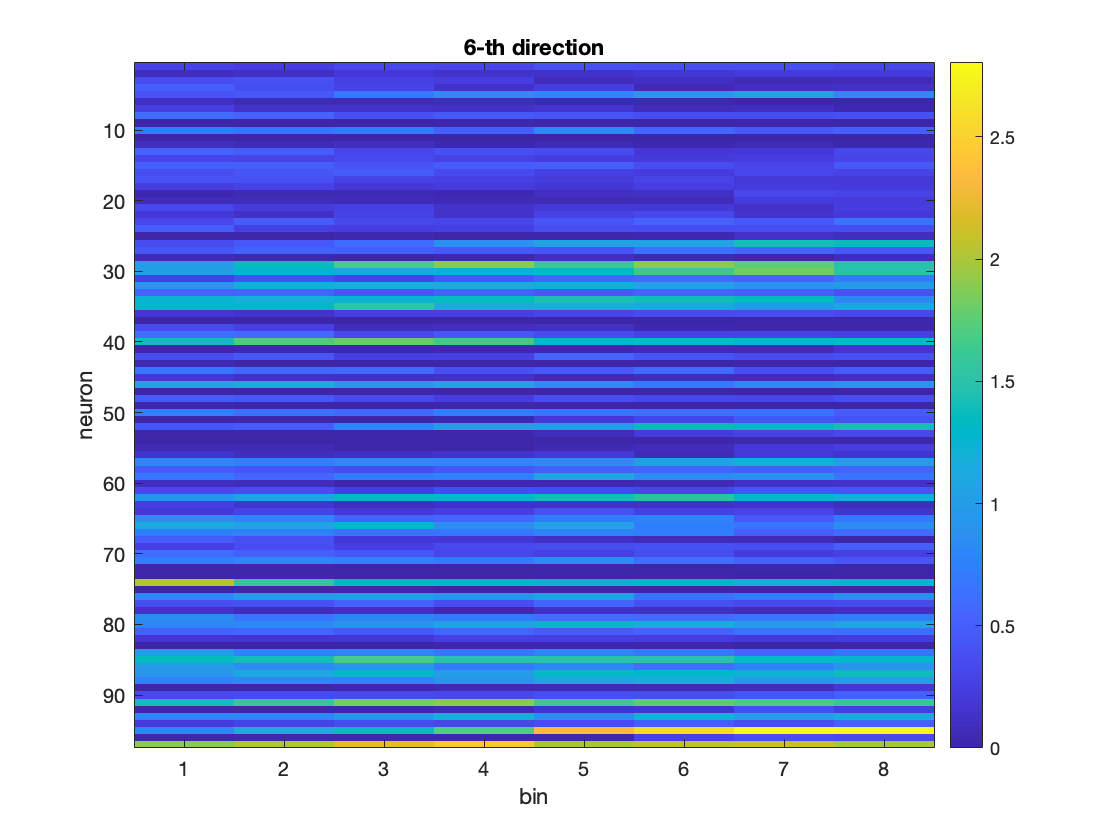

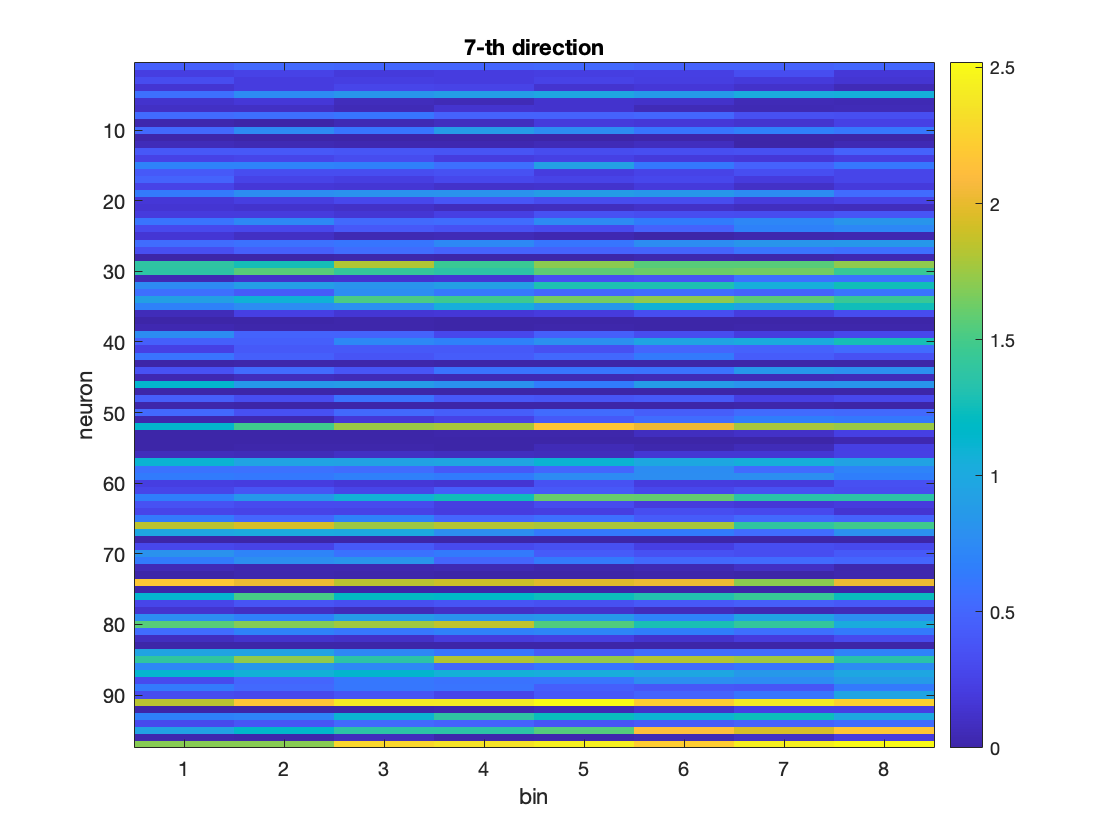

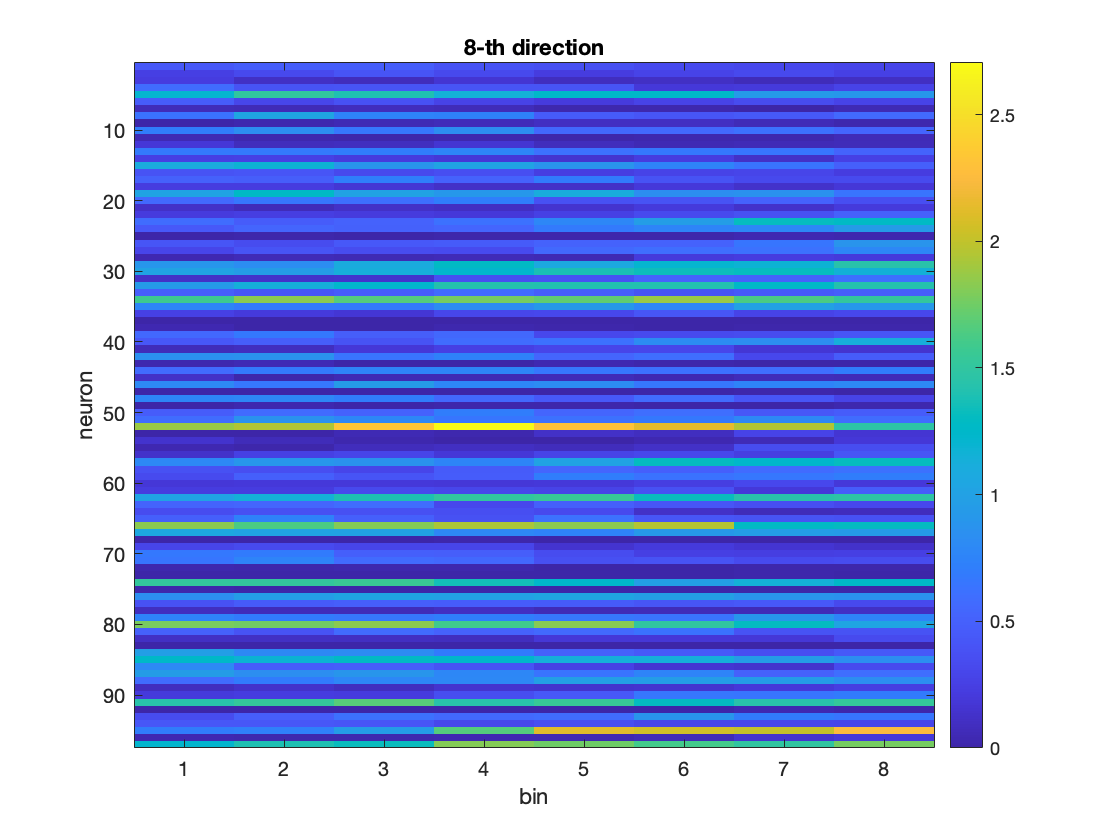

% 1a
shortest_time = inf;
longest_time = -inf;
T = zeros(91,8);
for n = 1:91
    for d = 1:8
        time = length(train_trial(n,d).spikes);
        T(n,d) = time;
        if time<shortest_time
            shortest_time = time;
        elseif time>longest_time
            longest_time = time;
        end
    end
end
T = floor(T/20);

max_num_bin = floor(longest_time/20);
min_num_bin = floor(shortest_time/20);
x = zeros(8*91,97,max_num_bin);

for d = 1:8
    for n = 1:91
        time = length(train_trial(n,d).spikes);
        for i = 1:floor(time/20)
            x((d-1)*91+n,:,i) = sum(train_trial(n,d).spikes(:,i*20-19:i*20),2);
        end
    end
end

for d = 1:8
    m = squeeze(mean(x(91*d-90:91*d,:,1:min_num_bin)));
    figure;
    imagesc(m);
    xlabel('bin');
    ylabel('neuron');
    title([int2str(d),'-th direction']);
    colorbar;
end

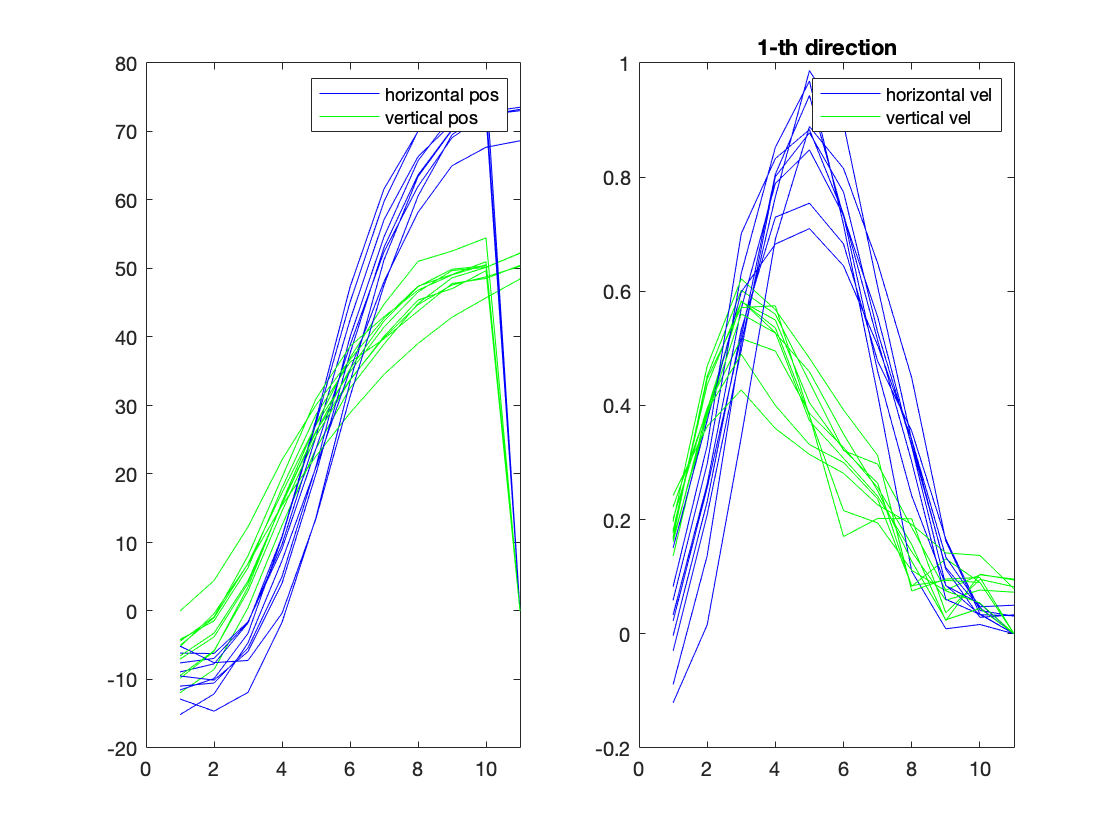

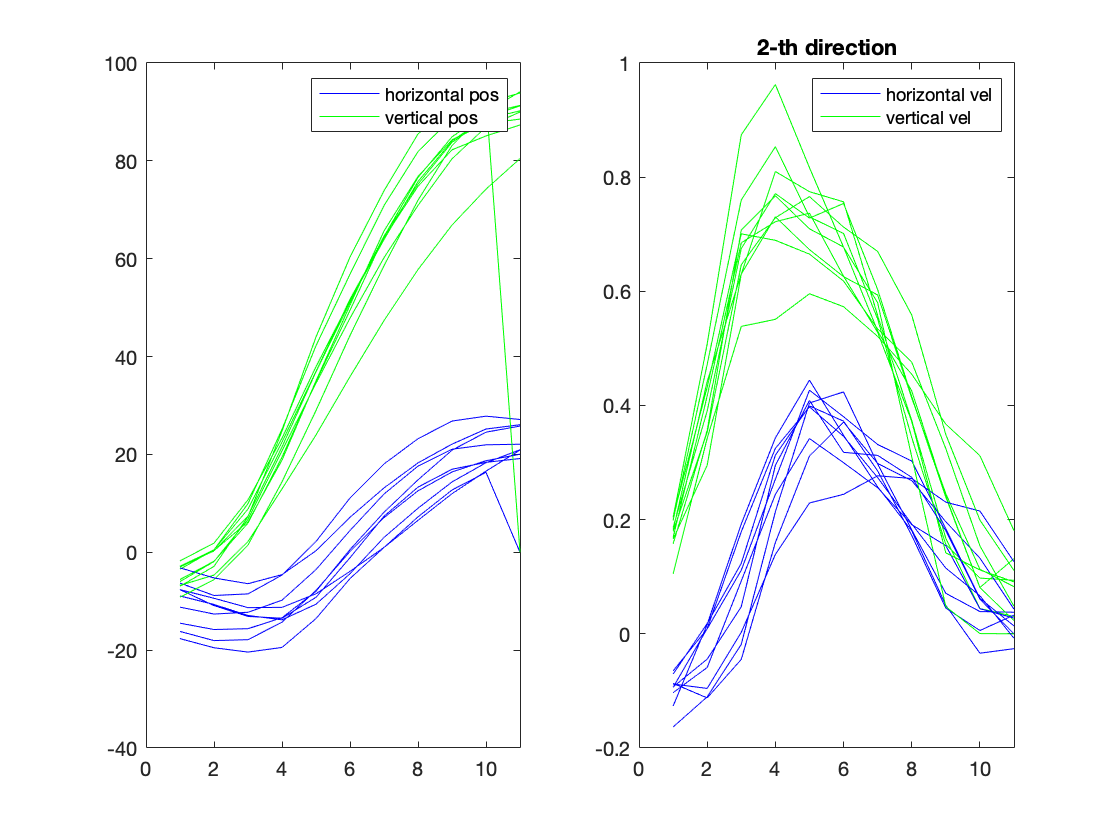

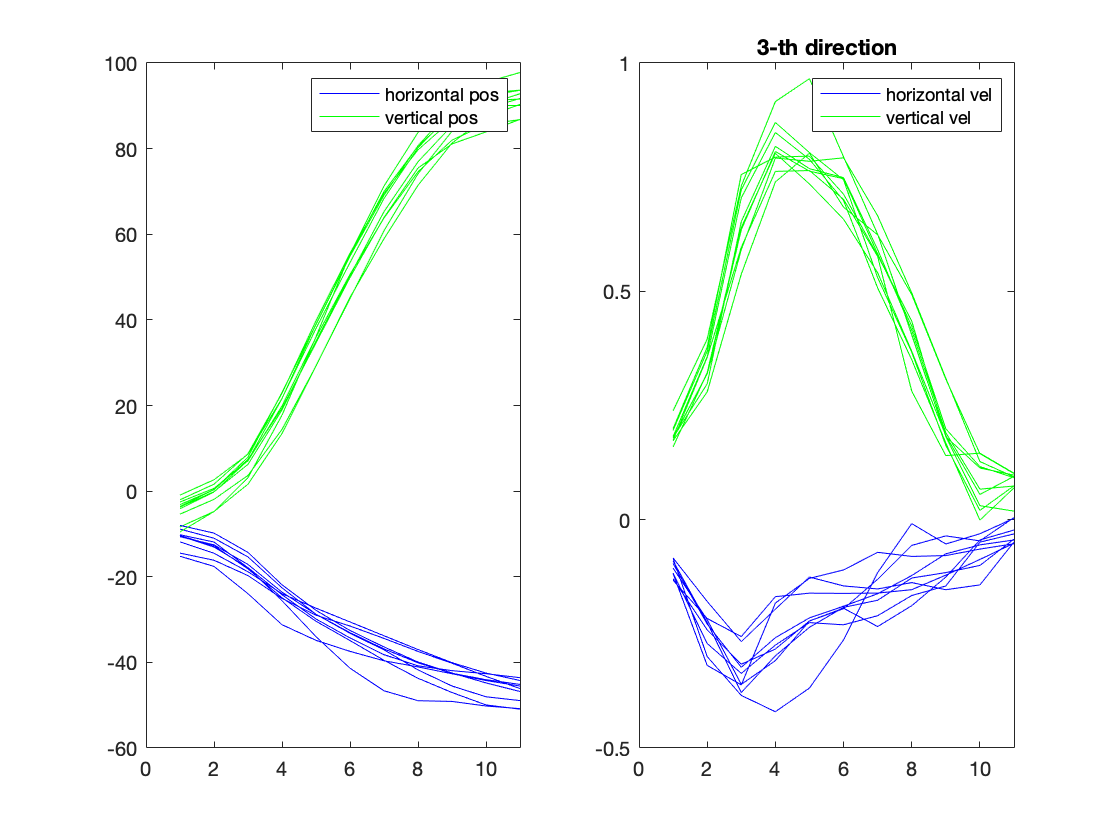

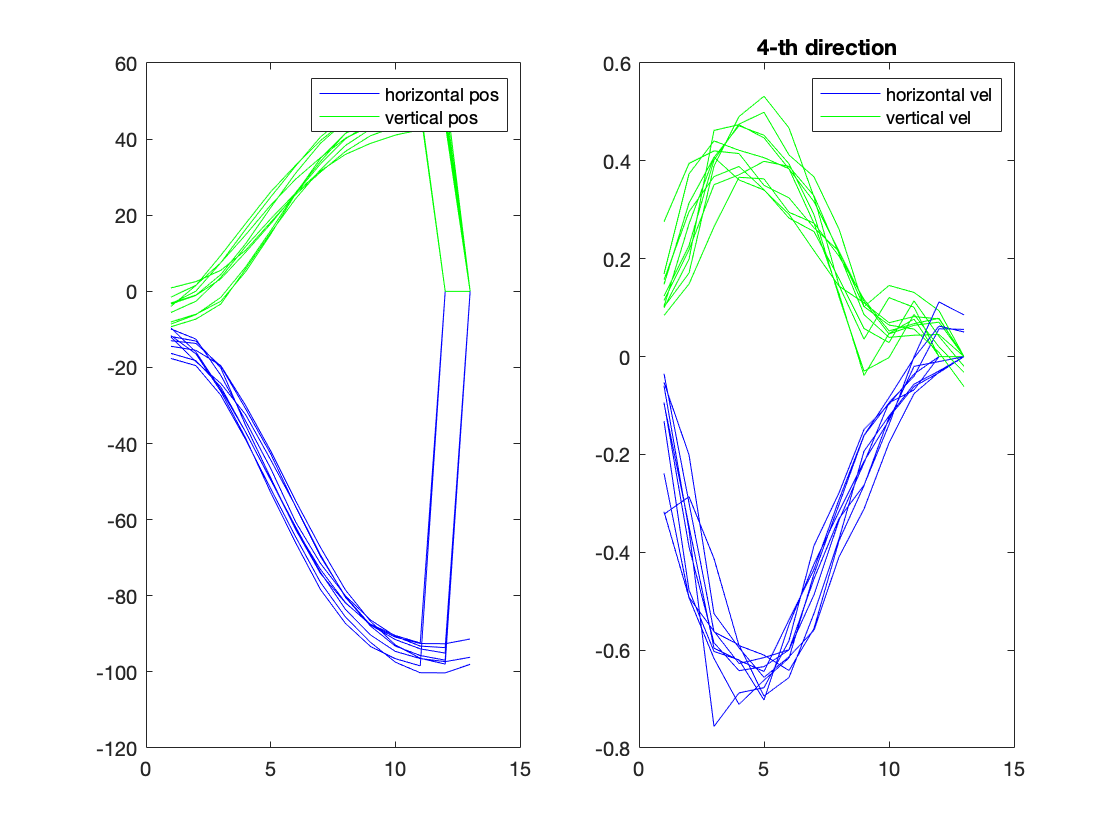

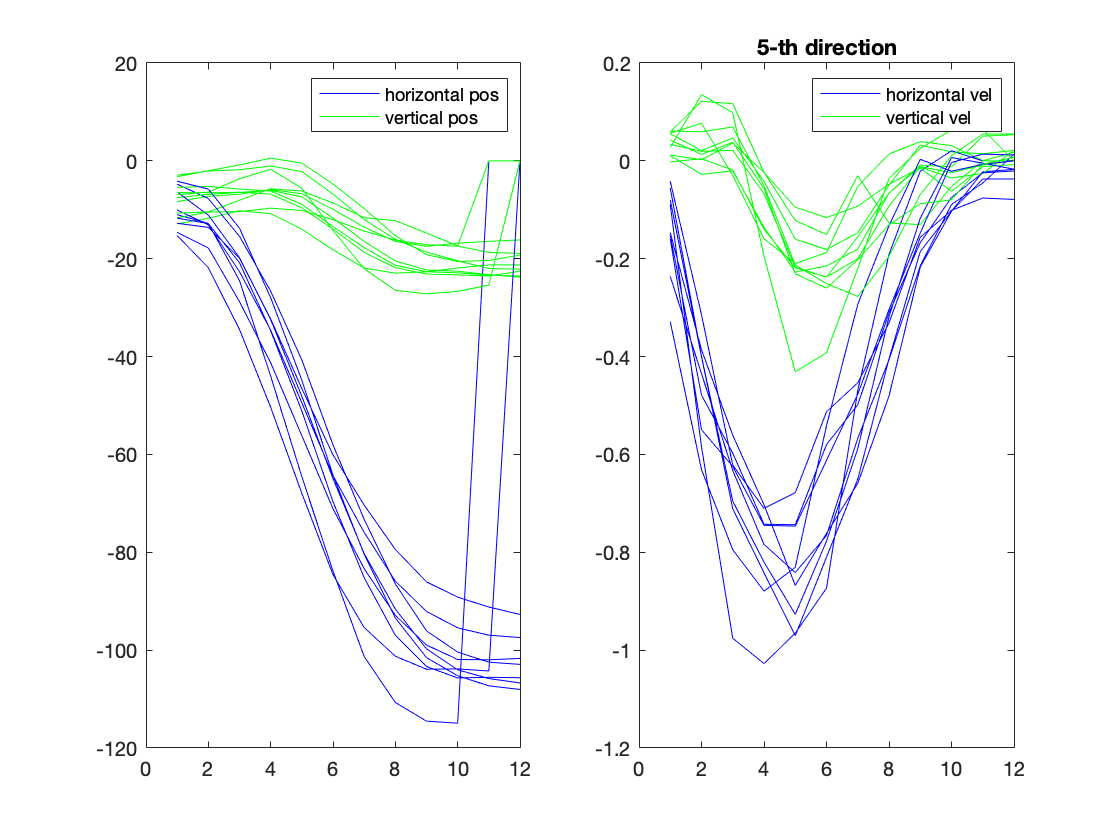

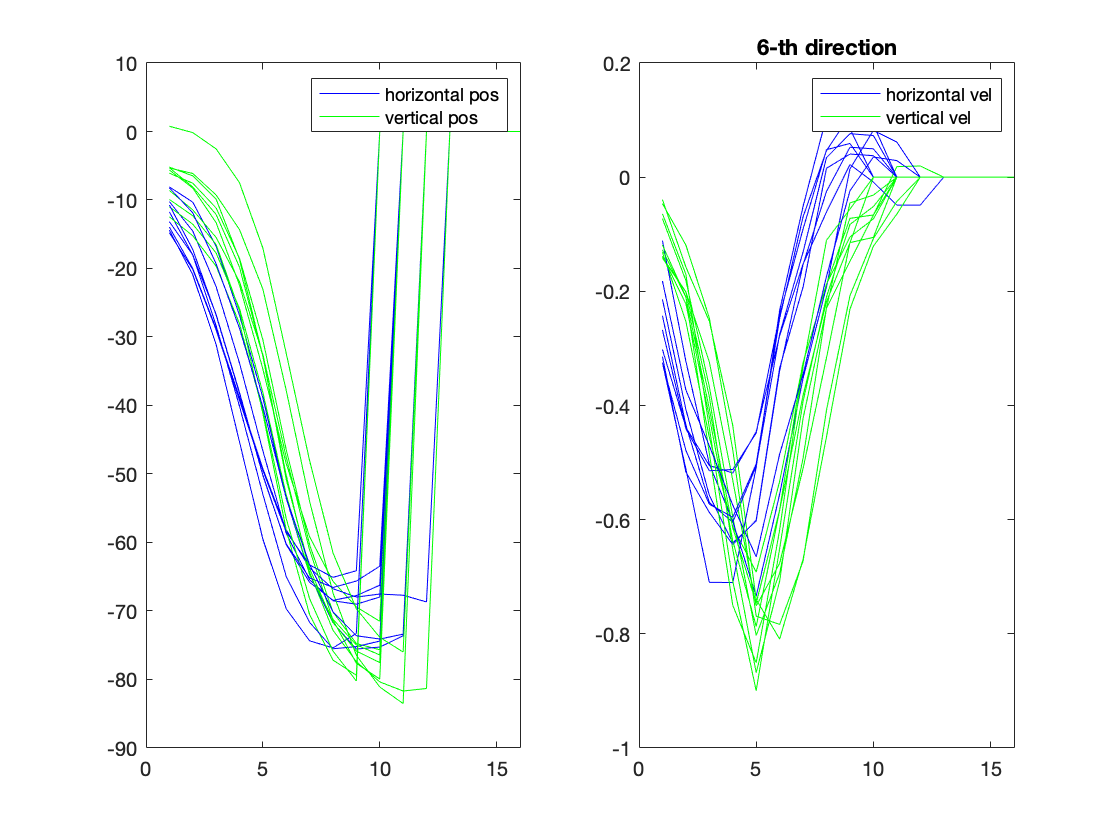

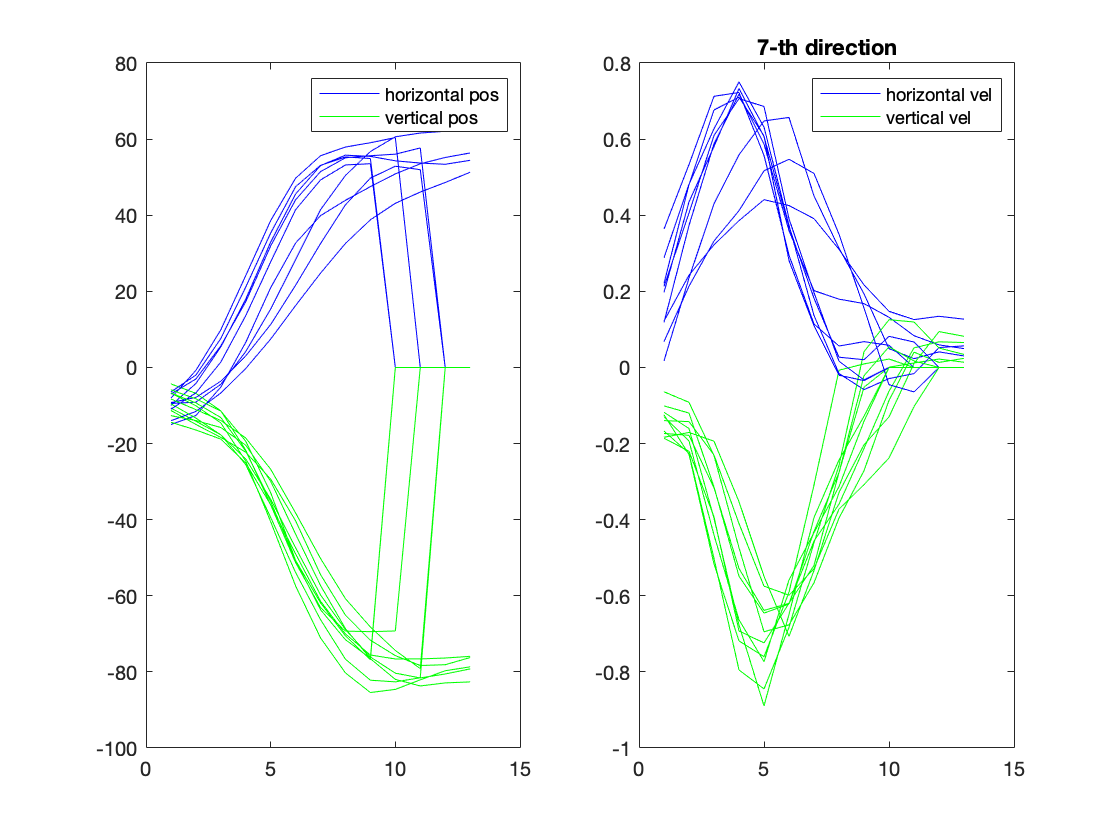

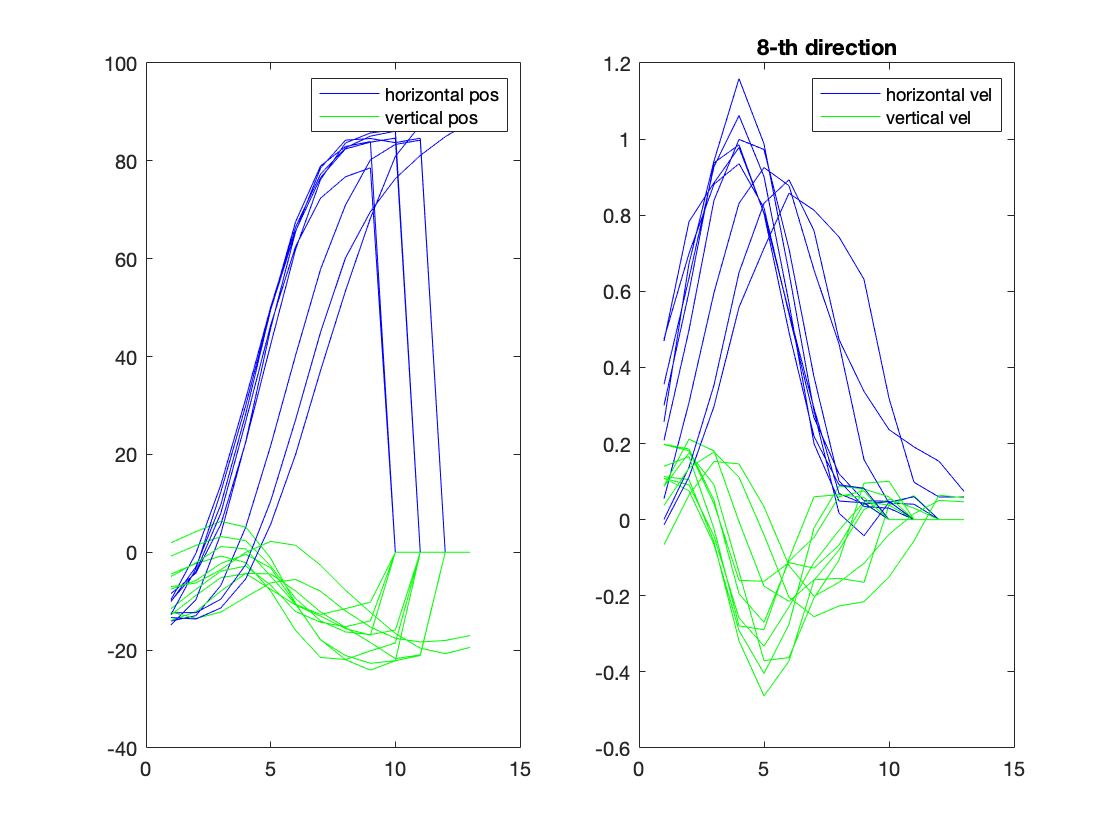

% 1b
z = zeros(91*8,4,max_num_bin);

for d = 1:8
    for n = 1:91
        for i = 1:T(n,d)
            handPos = train_trial(n,d).handPos;
            z((d-1)*91+n,1:2,i) = handPos(1:2,20*i);
            if i==T(n,d)
                z((d-1)*91+n,3:4,i) = (handPos(1:2,length(handPos))-handPos(1:2,length(handPos)-20))/20;
            else
                z((d-1)*91+n,3:4,i) = (handPos(1:2,20*i+20)-handPos(1:2,20*i))/20;
            end
        end
    end
end

idx = 1:91;
for d = 1:8
    sidx = datasample(idx,10,'replace',false);
    figure;
    subplot(1,2,1);
    for i = 1:10
        h = plot(squeeze(z(sidx(i)+(d-1)*91,1,1:T(n,d))),'color','b');
        v = plot(squeeze(z(sidx(i)+(d-1)*91,2,1:T(n,d))),'color','g');
        hold on;
    end
    legend([h,v],'horizontal pos','vertical pos');
    
    subplot(1,2,2);
    for i = 1:10
        h = plot(squeeze(z(sidx(i)+(d-1)*91,3,1:T(n,d))),'color','b');
        v = plot(squeeze(z(sidx(i)+(d-1)*91,4,1:T(n,d))),'color','g');
        hold on;
    end
    legend([h,v],'horizontal vel','vertical vel');
    title([int2str(d),'-th direction']);
end

% 2
F1 = zeros(4);
F2 = zeros(4);
F3 = zeros(97,4);
F4 = zeros(4);
Q = zeros(4);
R = zeros(97);

for d = 1:8
    for n = 1:91
        idx = 91*(d-1)+n;
        % A
        % factor 1
        for t = 2:T(n,d)
            F1 = F1+z(idx,:,t)'*z(idx,:,t-1);
        end
        % factor 2
        for t = 2:T(n,d)
            F2 = F2+z(idx,:,t-1)'*z(idx,:,t-1);
        end
        
        % C
        % factor 3
        for t = 1:T(n,d)
            F3 = F3+x(idx,:,t)'*z(idx,:,t);
        end
        % factor 4
        F4 = F4+z(idx,:,T(n,d))'*z(idx,:,T(n,d));
    end
end

A = F1/F2;
C = F3/F4;
% disp(A);
% disp(C);

for d = 1:8
    for n = 1:91
        idx = 91*(d-1)+n;
        % Q
        for t = 2:T(n,d)
            f = z(idx,:,t)'-A*z(idx,:,t-1)';
            Q = Q+f*f';
        end
        % R
        for t = 1:T(n,d)
            f = x(idx,:,t)'-C*z(idx,:,t)';
            R = R+f*f';
        end
    end
end
Q = Q./(sum(T(:))-728);
R = R./sum(T(:));
% disp(Q);
% disp(R);
pi = mean(z(:,:,1))';
V = cov(z(:,:,1));

A =

    1.0000    0.0000   20.0000   -0.0000

    0.0000    1.0000   -0.0000   20.0000

   -0.0014   -0.0006    1.0173    0.0602

    0.0001   -0.0013   -0.0321    1.0160

Q =

    0.0000    0.0000    0.0000   -0.0000

    0.0000    0.0000   -0.0000   -0.0000

    0.0000   -0.0000    0.0163   -0.0005

   -0.0000   -0.0000   -0.0005    0.0134

We denote the horizontal and vertical position at time t as h_t and v_t respectively; the horizontal and vertical speed at time t as  vh_t and vv_t, respectively.

Then the values of A shows the following relationship between adjacent states:

h_{t+1} = h_t + 20 vh_t

v_{t+1} = v_t + 20 vv_t

The above relationship complies with the physical model.

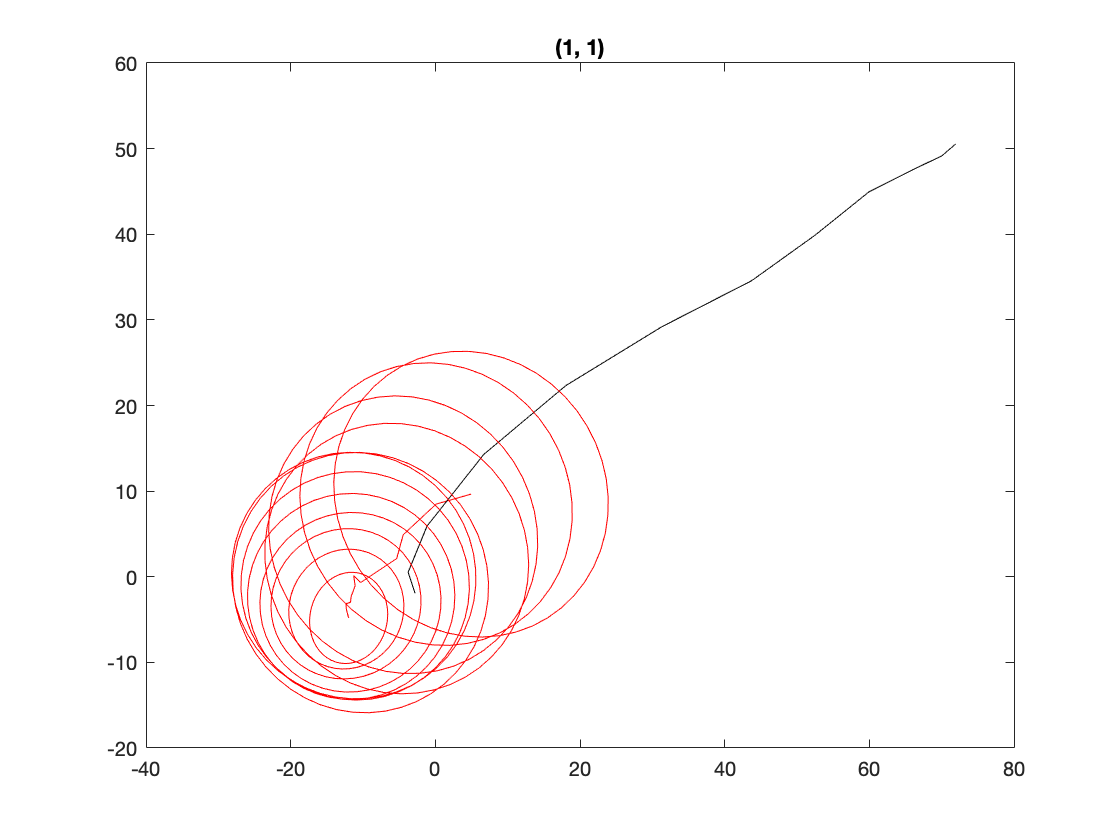

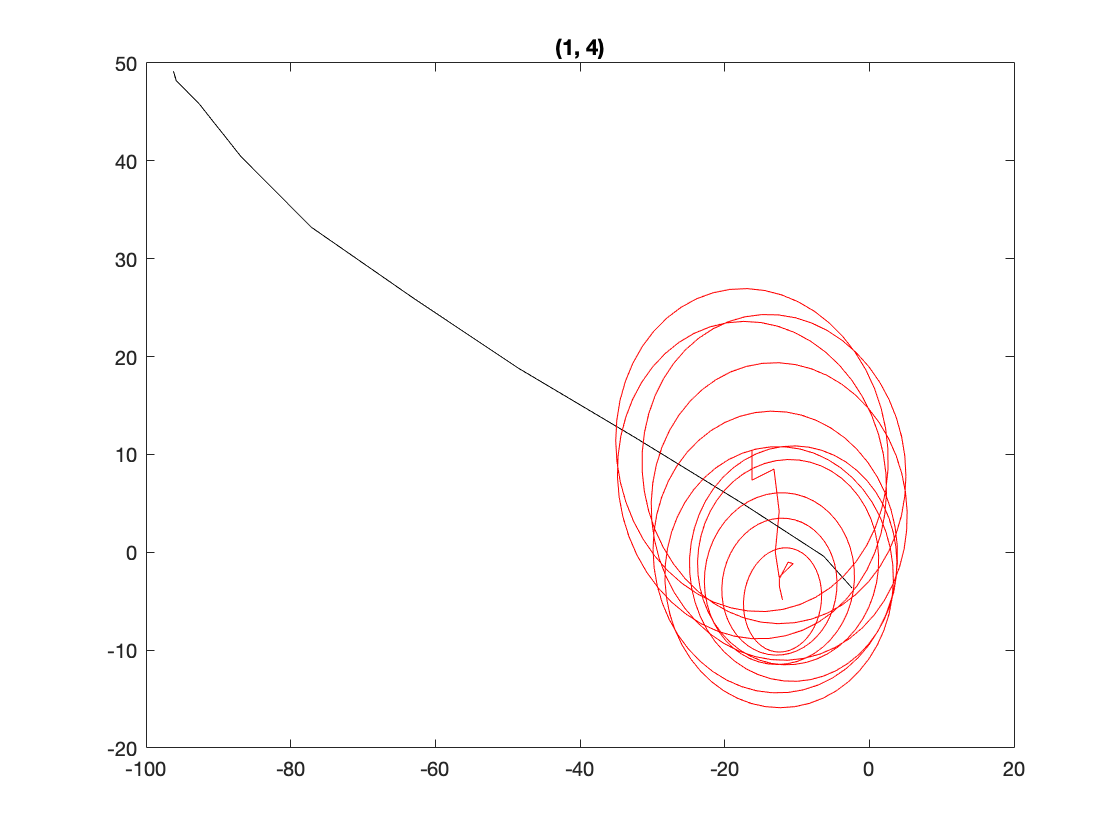

% 3
T = zeros(91,8);
for n = 1:91
    for d = 1:8
        time = length(test_trial(n,d).spikes);
        T(n,d) = time;
        if time<shortest_time
            shortest_time = time;
        elseif time>longest_time
            longest_time = time;
        end
    end
end
T = floor(T/20);

max_num_bin = floor(longest_time/20);
% min_num_bin = floor(shortest_time/20);
x = zeros(8*91,97,max_num_bin);

for d = 1:8
    for n = 1:91
        time = length(test_trial(n,d).spikes);
        for i = 1:floor(time/20)
            x((d-1)*91+n,:,i) = sum(test_trial(n,d).spikes(:,i*20-19:i*20),2);
        end
    end
end

z = zeros(91*8,4,max_num_bin);
for d = 1:8
    for n = 1:91
        for i = 1:T(n,d)
            handPos = test_trial(n,d).handPos;
            z((d-1)*91+n,1:2,i) = handPos(1:2,20*i);
            if i==T(n,d)
                z((d-1)*91+n,3:4,i) = (handPos(1:2,length(handPos))-handPos(1:2,length(handPos)-20))/20;
            else
                z((d-1)*91+n,3:4,i) = (handPos(1:2,20*i+20)-handPos(1:2,20*i))/20;
            end
        end
    end
end

trajectory = zeros(728,2,max_num_bin);

for d = 1:8
    for n = 1:91
        idx = 91*(d-1)+n;
        % decode init
        mu = pi;
        sigma = V;
        for t = 1:T(n,d)
            % prediction
            mu = A*mu;
            sigma = A*sigma*A'+Q;
            % update
            K = sigma*C'/(C*sigma*C'+R);
            mu = mu+K*(x(idx,:,t)'-C*mu);
            sigma = sigma-K*C*sigma;
            trajectory(idx,:,t) = mu(1:2);
        end
    end
end

% plot (1,1) and (1,4)
for i = 1:2
    n = 1;
    if i==1
        d = 1;
    else
        d = 4;
    end
    idx = 91*(d-1)+n;
    traj = squeeze(trajectory(idx,1:2,1:T(n,d)));
    figure;
    plot(traj(1,:),traj(2,:),'color','r');
    hold on;
    gt = squeeze(z(idx,1:2,1:T(n,d)));
    plot(gt(1,:),gt(2,:),'color','k');
    title(['(',num2str(n),', ',num2str(d),')']);
    
    % decode init
    mu = pi;
    sigma = V;
    for t = 1:T(n,d)
        % prediction
        mu = A*mu;
        sigma = A*sigma*A'+Q;
        % update
        K = sigma*C'/(C*sigma*C'+R);
        mu = mu+K*(x(idx,:,t)'-C*mu);
        sigma = sigma-K*C*sigma;
        hold on;
        h = plot_gaussian_ellipsoid(mu(1:2),sigma(1:2,1:2));
        set(h,'color','r'); 
    end
end


% evaluate accuracy
diff = trajectory-z(:,1:2,:);
diff = squeeze(diff);
scalar_diff = zeros(728,1);
for d = 1:8
    for n = 1:91
        idx = 91*(d-1)+n;
        d_trial = squeeze(diff(idx,:,1:T(n,d)));
        scalar_diff(idx) = mean(vecnorm(d_trial));
    end
end

disp(['aveage error is ',num2str(mean(scalar_diff)),' mm']);

aveage error is 55.4375 mm
